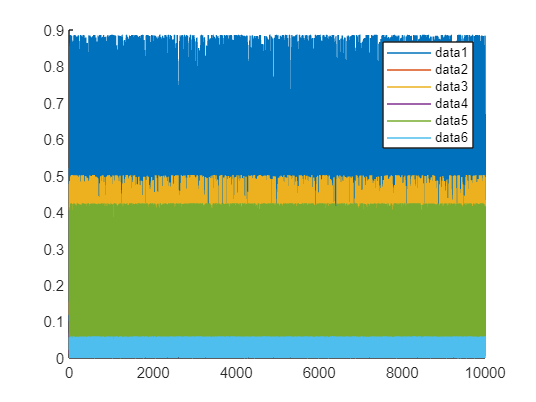

clear all;
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
scatter_number=100-1;
theta=[0:pi/scatter_number:pi];
phi=[0:2*pi/scatter_number:pi*2];
inital_state=[1 0 0 0 0 0]';
sample_num=10000;center=0.3;sigma=1;
density_matrix=zeros(6,6);
for i=1:sample_num
    distribution=normrnd(center,sigma);
    ham_piover2=sigmay;
    ham_precession=1*sigmaz+1*distribution.*sigmaz^2;
    transverse_polar=ham_evolve(ham_piover2,inital_state,pi/2);
    precess_state=ham_evolve(ham_precession,transverse_polar,10000);
    final_state=ham_evolve(ham_piover2,precess_state,pi/2);
    singlestate_population(:,i)=abs(final_state).^2;
    
    

    density_matrix=precess_state*precess_state'+density_matrix;
    %density_matrix=final_state*final_state'+density_matrix;
end
density_matrix=density_matrix./sample_num;
figure;hold on;
for i=1:6
    plot([1:sample_num],singlestate_population(i,:));
end
legend;

average_population=sum(singlestate_population,2)/sample_num;

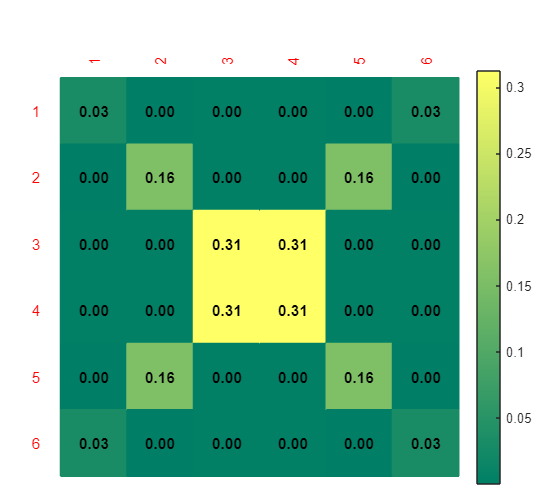


figure;
matrixplot(abs(density_matrix),'DisplayOpt','On','ColorBar','On','Grid','Off', ...
    'XVarName',{'1' '2' '3' '4' '5' '6'}, 'YVarName',{'1' '2' '3' '4' '5' '6'});
colormap summer;

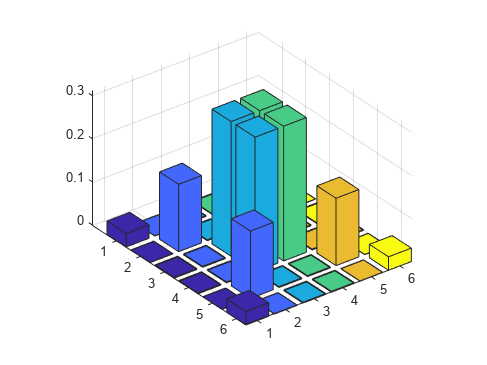

%set(gca,"Clim",[0 1]);
for i=1:length(theta)
    theta_in=theta(i);
    for j=1:length(phi)
        phi_in=phi(j);
        result(i,j)=spin_coherent(theta_in,phi_in)'*density_matrix*spin_coherent(theta_in,phi_in);
    end
end
figure;
bar3(abs(density_matrix));

trace(density_matrix^2)

ans = 0.4923

%zlim([0 1])

## Plot

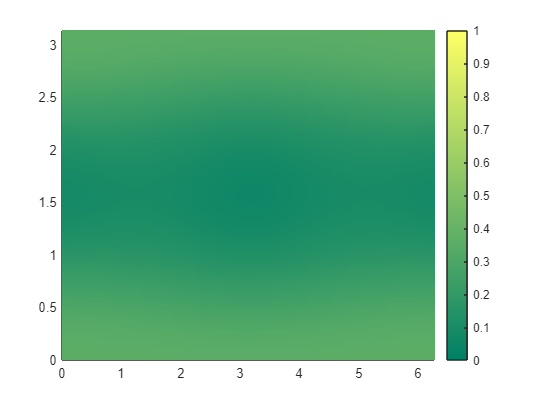

figure;
output=pcolor(phi,theta,abs(result));
output.LineStyle="none";
set(gca,"Clim",[0 1]);
colormap summer;colorbar;grid off;

## Fisher information

%density_matrix=[0.03125 0 0 0 0 0.03125;0 0.15625 0 0 0.15625 0;0 0 0.3125 0.3125 0 0;
%0 0 0.3125 0.3125 0 0; 0 0.15625 0 0 0.15625 0; 0.03125 0 0 0 0 0.03125];
fisher_information(density_matrix,sigmaz)

ans = 4.6820

state=sqrt([1 5 10 10 5 1]')./sqrt(32);
state=sqrt([1 0 0 0 0 1]')./sqrt(2);
delta_H_2=state'*sigmaz^2*state-(state'*sigmaz*state)^2;
delta_H_2 = delta_H_2 * 4

delta_H_2 = 25.0000

function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end